**Important information: **

Rearth = 6378 \text{ km} \mu_{\text{earth}} = 3.986 \times 10^5 \text{ km}^3/\text{s}^2 J_2 = 0.00108263

1. Apply the Newton-Raphson method to find a root of the function:

   \[

   f(t) = \sin(t) + 3e^{\frac{t}{10}} \cos(t) - 4

   \]

    Use an initial guess \( t_n = 5 \), and show the results of each step in a table, similar to the Kepler's            Problem Example in the lecture slides. The table should contain two columns: \( t_n \) and \( f(t_n) \).  Continue iterating until \( |f(t_n)| < 10^{-10} \), and display 12 decimal places in the output table.

    What happens if you use the initial guess \( t_n = 7 \)? Repeat the process and compare the results.

    Make a graph of \( f(t) \), and use it to discuss the results of your numerical solutions.

% Define the function f(t) and its derivative f'(t)
f = @(t) sin(t) + 3 .* exp(t / 10) .* cos(t) - 4;
df = @(t) cos(t) + (3 / 10) .* exp(t / 10) .* cos(t) - 3 .* exp(t / 10) .* sin(t);

% Parameters
tol = 1e-10;
max_iter = 100;

% Arrays to store iterations
iterations_5 = [];
values_5 = [];
iterations_7 = [];
values_7 = [];

% Newton-Raphson method implementation (for t0 = 5)
t0_5 = 5;
tn = t0_5;
fn = f(tn);
% Store the initial guess and function value
iterations_5 = [iterations_5; tn];
values_5 = [values_5; fn];

for i = 1:max_iter
    dfn = df(tn);
    tn_new = tn - fn / dfn;
    fn_new = f(tn_new);
    
    % Store the current iteration values
    iterations_5(end+1) = tn_new;
    values_5(end+1) = fn_new;
    
    % Check for convergence
    if abs(fn_new) < tol
        break;
    end
    
    % Update tn for the next iteration
    tn = tn_new;
    fn = fn_new;
end

% Newton-Raphson method implementation (for t0 = 7)
t0_7 = 7;
tn = t0_7;
fn = f(tn);
% Store the initial guess and function value
iterations_7 = [iterations_7; tn];
values_7 = [values_7; fn];

for i = 1:max_iter
    dfn = df(tn);
    tn_new = tn - fn / dfn;
    fn_new = f(tn_new);
    
    % Store the current iteration values
    iterations_7(end+1) = tn_new;
    values_7(end+1) = fn_new;
    
    % Check for convergence
    if abs(fn_new) < tol
        break;
    end
    
    % Update tn for the next iteration
    tn = tn_new;
    fn = fn_new;
end

% Print results for t0 = 5
fprintf('Results for initial guess t0 = 5:\n');

Results for initial guess t0 = 5:


fprintf('   t                          f(t)\n');

   t                          f(t)


fprintf('--------------------------------------------\n');

--------------------------------------------


for i = 1:length(iterations_5)
    fprintf('%.12f  %.12e\n', iterations_5(i), values_5(i));
end

5.000000000000  -3.555884638064e+00
5.688196305636  -1.724863659383e-01
5.728907897178  -2.699518013623e-03
5.729565867219  -7.344808250487e-07
5.729566046336  -5.595524044111e-14



% Print results for t0 = 7
fprintf('\nResults for initial guess t0 = 7:\n');


Results for initial guess t0 = 7:


fprintf('   t                          f(t)\n');

   t                          f(t)


fprintf('--------------------------------------------\n');

--------------------------------------------


for i = 1:length(iterations_7)
    fprintf('%.12f  %.12e\n', iterations_7(i), values_7(i));
end

7.000000000000  1.211504716275e+00
7.439003225585  -5.399120883241e-01
7.333530004238  -2.636963924124e-02
7.327811460827  -8.230505922047e-05
7.327793499879  -8.142695406832e-10
7.327793499701  8.881784197001e-16


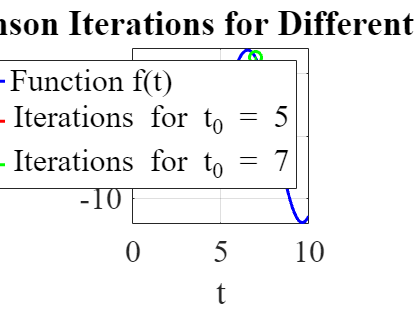


% Define a range for plotting the function
t_range = linspace(0, 10);
f_range = f(t_range);

% Define font size variable
fs = 16; % You can adjust this value as needed

% Plot the function and the iteration points
figure;
plot(t_range, f_range, 'b-', 'LineWidth', 1.5); % Plot the function
hold on;
plot(iterations_5, values_5, 'ro-', 'MarkerSize', 6, 'LineWidth', 1.5); % Plot iterations for t0 = 5
plot(iterations_7, values_7, 'go-', 'MarkerSize', 6, 'LineWidth', 1.5); % Plot iterations for t0 = 7
hold off;

% Add labels and legend with font size and type settings
xlabel('t', 'FontSize', fs, 'FontName', 'Times New Roman');
ylabel('f(t)', 'FontSize', fs, 'FontName', 'Times New Roman');
title('Newton-Raphson Iterations for Different Initial Guesses', 'FontSize', fs, 'FontName', 'Times New Roman');
legend('Function f(t)', 'Iterations for t_0 = 5', 'Iterations for t_0 = 7', 'FontSize', 16, 'FontName', 'Times New Roman');
grid on;

% Set the font of the entire figure to Times New Roman and size to fs
set(gca, 'FontSize', fs, 'FontName', 'Times New Roman');

% Ensure the axes are equal and set x-axis limits
axis square;
xlim([0 10]);
ylim([-12, 2])

2. An Earth-orbiting satellite is in a 450-km parking orbit. The mission orbit is a 1400-km orbit in the same plane. For each of the orbit transfers below, the initial $\Delta v$ puts the satellite on a transfer orbit or trajectory at perigee. The second $\Delta v$ transfers the satellite from the transfer orbit to the mission orbit. For each of the orbit transfers, determine the individual and total $\Delta v$'s and the time-of-flight. Your answers should be in km/s and minutes.

Hohmann transfer

% Constants
mu = 3.986e5; % Gravitational parameter for Earth [km^3/s^2]
R_Earth = 6378; % Radius of Earth [km]

% Orbit radii (include Earth's radius in the calculation)
r1 = 450 + R_Earth; % Radius of the parking orbit [km]
r2 = 1400 + R_Earth; % Radius of the mission orbit [km]

[dv1, dv2, dvt, T_transfer] = hohmann_transfer(r1, r2, mu);
T_transfer_min = T_transfer/60;

% Display results
fprintf('Hohmann Transfer:\n');

Hohmann Transfer:


fprintf('Initial Delta-v (km/s): %.4f\n', dv1);

Initial Delta-v (km/s): 0.2446


fprintf('Final Delta-v (km/s): %.4f\n', dv2);

Final Delta-v (km/s): 0.2367


fprintf('Total Delta-v (km/s): %.4f\n', dvt);

Total Delta-v (km/s): 0.4813


fprintf('Time-of-Flight (minutes): %.2f\n', T_transfer_min);

Time-of-Flight (minutes): 51.76


 Elliptical orbit with a equal to twice the Hohmann transfer semimajor axis.

% Constants
mu = 3.986e5; % Gravitational parameter for Earth [km^3/s^2]
R_Earth = 6378; % Radius of Earth [km]

% Orbit radii (include Earth's radius in the calculation)
r1 = 450 + R_Earth; % Radius of the parking orbit [km]
r2 = 1400 + R_Earth; % Radius of the mission orbit [km]

% Velocities in initial and final orbits
v1 = sqrt(mu / r1); % velocity in the parking orbit
v2 = sqrt(mu / r2); % velocity in the mission orbit

% Semi-major axis of the Hohmann transfer orbit
a_hohmann = (r1 + r2) / 2;
a_ellip = 2 * a_hohmann; % semi-major axis of the elliptical orbit

% Velocities at periapsis and apoapsis of the elliptical transfer orbit
v1_ellip = sqrt(mu * (2 / r1 - 1 / a_ellip)); % velocity at periapsis (r1)
v2_ellip = sqrt(mu * (2 / r2 - 1 / a_ellip)); % velocity at apoapsis (r2)

% Delta-V calculations
dv1 = v1_ellip - v1; % first burn (at periapsis)
dv2 = v2 - v2_ellip;  % second burn (at apoapsis)
dvt = abs(dv1) + abs(dv2); % total Delta-V for the transfer

rp = r1;
e = 1 - rp/a_ellip;

E = acos((1-(r2/a_ellip))/e);
dt = sqrt(a_ellip^3/mu)*(2*pi + (E - e*sin(E)));

% Convert time to minutes and display the result
T_transfer_min = dt / 60;

% Display results
fprintf('Elliptical orbit with semi-major axis equal to twice the Hohmann transfer semi-major axis:\n');

Elliptical orbit with semi-major axis equal to twice the Hohmann transfer semi-major axis:


fprintf('Initial Delta-v (km/s): %.4f\n', dv1);

Initial Delta-v (km/s): 1.8181


fprintf('Final Delta-v (km/s): %.4f\n', dv2);

Final Delta-v (km/s): -1.5133


fprintf('Total Delta-v (km/s): %.4f\n', dvt);

Total Delta-v (km/s): 3.3314


fprintf('Time-of-Flight (minutes): %.2f\n', T_transfer_min);

Time-of-Flight (minutes): 304.18


Parabolic trajectory

% Constants
mu = 3.986e5; % Gravitational parameter for Earth [km^3/s^2]
R_Earth = 6378; % Radius of Earth [km]

% Orbit radii (include Earth's radius in the calculation)
r1 = 450 + R_Earth; % Radius of the parking orbit [km]
r2 = 1400 + R_Earth; % Radius of the mission orbit [km]

% Velocities in initial and final orbits
v1 = sqrt(mu / r1); % velocity in the parking orbit
v2 = sqrt(mu / r2); % velocity in the mission orbit

v1_par = sqrt(mu * (2 / r1));
v2_par = sqrt(mu * (2 / r2));

% Delta-V calculations
dv1 = v1_par - v1; % first burn (at periapsis)
dv2 = v2 - v2_par;  % second burn (at apoapsis)
dvt = abs(dv1) + abs(dv2); % total Delta-V for the transfer

% Given parameters for a parabolic orbit
rp = r1;    % Periapsis distance
e = 1;      % Eccentricity for a parabolic orbit
p = 2 * rp; % Semi-latus rectum for a parabolic orbit

nu2_rad = acos((p - r2) / r2);  % Calculate from orbital geometry

% Calculate the time of flight for a parabolic trajectory
D = sqrt(p)*tan(nu2_rad/2);
dt = 1/(2*sqrt(mu))*(p*D + D^3/3);

% Convert time to minutes and display the result
T_transfer_min = dt / 60;

% Display results
fprintf('Parabolic Transfer:\n');

Parabolic Transfer:


fprintf('Initial Delta-v (km/s): %.4f\n', dv1);

Initial Delta-v (km/s): 3.1648


fprintf('Final Delta-v (km/s): %.4f\n', dv2);

Final Delta-v (km/s): -2.9652


fprintf('Total Delta-v (km/s): %.4f\n', dvt);

Total Delta-v (km/s): 6.1300


fprintf('Time-of-Flight (minutes): %.2f\n', T_transfer_min);

Time-of-Flight (minutes): 8.22


Hyperbolic trajectory with |a| equal to twice the Hohmann transfer semimajor axis

% Constants
mu = 3.986e5; % Gravitational parameter for Earth [km^3/s^2]
R_Earth = 6378; % Radius of Earth [km]

% Orbit radii (include Earth's radius in the calculation)
r1 = 450 + R_Earth; % Radius of the parking orbit [km]
r2 = 1400 + R_Earth; % Radius of the mission orbit [km]

% Velocities in initial and final orbits
v1 = sqrt(mu / r1); % velocity in the parking orbit
v2 = sqrt(mu / r2); % velocity in the mission orbit

% Semi-major axis of the Hohmann transfer orbit
a_hohmann = (r1 + r2) / 2;
a_hyp = -2 * a_hohmann; % semi-major axis of the hyperbolic orbit

% Velocities at periapsis and apoapsis of the elliptical transfer orbit
v1_hyp = sqrt(mu * (2 / r1 - 1 / a_hyp)); % velocity at periapsis (r1)
v2_hyp = sqrt(mu * (2 / r2 - 1 / a_hyp)); % velocity at apoapsis (r2)

% Delta-V calculations
dv1 = v1_hyp - v1; % first burn (at periapsis)
dv2 = v2 - v2_hyp;  % second burn (at apoapsis)
dvt = abs(dv1) + abs(dv2); % total Delta-V for the transfer

rp = r1;
e = -rp/a_hyp + 1;
F = acosh((1-r2/a_hyp)/e);
dt = sqrt(-a_hyp^3/mu)*(e*sinh(F) - F);

% Convert time to minutes and display the result
T_transfer_min = dt / 60;

% Display results
fprintf('Hyperbolic trajectory with |a| equal to twice the Hohmann transfer semimajor axis:\n');

Hyperbolic trajectory with |a| equal to twice the Hohmann transfer semimajor axis:


fprintf('Initial Delta-v (km/s): %.4f\n', dv1);

Initial Delta-v (km/s): 4.3614


fprintf('Final Delta-v (km/s): %.4f\n', dv2);

Final Delta-v (km/s): -4.2336


fprintf('Total Delta-v (km/s): %.4f\n', dvt);

Total Delta-v (km/s): 8.5949


fprintf('Time-of-Flight (minutes): %.2f\n', T_transfer_min);

Time-of-Flight (minutes): 6.76


**Extra Credit Problem. Counts as an additional Homework 10 points.** For the orbit transfer scenario in the previous problem, create professional quality graphs of ∆t vs e and ∆v vs e with e ∈ [emin, emax], where emin is the eccentricity of the Hohmann transfer, and emax is the eccentricity of the hyperbolic trajectory. On each graph label the points corresponding to the Hohmann and parabolic transfers. Include the code you wrote for this problem as an appendix. As with all other problems, your presentation should be in a report format, with steps explained using complete sentences.

% Constants
mu = 3.986e5; % Gravitational parameter for Earth [km^3/s^2]
R_Earth = 6378; % Radius of Earth [km]
r1 = 450 + R_Earth; % Radius of the parking orbit [km]
r2 = 1400 + R_Earth; % Radius of the mission orbit [km]

% Eccentricity range
eccentricity = [0.065:0.005:0.9, 1:0.0005:1.4675]; % Varying eccentricity

% Preallocate arrays for results
deltaV = zeros(size(eccentricity));
dt = zeros(size(eccentricity));
orbit_type = zeros(size(eccentricity)); % 1 for elliptical, 2 for parabolic, 3 for hyperbolic

for i = 1:length(eccentricity)
    e = eccentricity(i);
    
    if e < 1
        % Elliptical Orbits
        a_ellip = r1/(1-e); % semi-major axis of the elliptical orbit
        v1_ellip = sqrt(mu * (2 / r1 - 1 / a_ellip)); % velocity at periapsis (r1)
        v2_ellip = sqrt(mu * (2 / r2 - 1 / a_ellip)); % velocity at apoapsis (r2)
        dv1_ellip = v1_ellip - sqrt(mu / r1); % first burn (at periapsis)
        dv2_ellip = sqrt(mu / r2) - v2_ellip; % second burn (at apoapsis)
        deltaV(i) = abs(dv1_ellip) + abs(dv2_ellip);

        E = acos((1 - r2 / a_ellip) / e);
        dt(i) = sqrt(a_ellip^3 / mu) * (2 * pi + (E - e * sin(E)));
        orbit_type(i) = 1; % 1 for elliptical

    elseif e == 1
        % Parabolic Orbits
        v1_par = sqrt(mu * (2 / r1));
        v2_par = sqrt(mu * (2 / r2));
        dv1_par = v1_par - sqrt(mu / r1); % first burn (at periapsis)
        dv2_par = sqrt(mu / r2) - v2_par; % second burn (at apoapsis)
        deltaV(i) = abs(dv1_par) + abs(dv2_par);

        % Semi-latus rectum for a parabolic orbit
        p = 2 * r1; % Semi-latus rectum
        nu2_rad = acos((p - r2) / r2); % Calculate from orbital geometry
        D = sqrt(p) * tan(nu2_rad / 2);
        dt(i) = 1 / (2 * sqrt(mu)) * (p * D + D^3 / 3);
        orbit_type(i) = 2; % 2 for parabolic

    else
        % Hyperbolic Orbits
        a_hyp = r1/(1-e); % semi-major axis of the hyperbolic orbit
        v1_hyp = sqrt(mu * (2 / r1 - 1 / a_hyp)); % velocity at periapsis (r1)
        v2_hyp = sqrt(mu * (2 / r2 - 1 / a_hyp)); % velocity at apoapsis (r2)
        dv1_hyp = v1_hyp - sqrt(mu / r1); % first burn (at periapsis)
        dv2_hyp = sqrt(mu / r2) - v2_hyp; % second burn (at apoapsis)
        deltaV(i) = abs(dv1_hyp) + abs(dv2_hyp);

        F = acosh((1 - r2 / a_hyp) / e);
        dt(i) = sqrt(-a_hyp^3 / mu) * (e * sinh(F) - F);
        orbit_type(i) = 3; % 3 for hyperbolic
    end
end

% Define font size variable
fs = 18; % You can adjust this value as needed

% Define indices for special points
hohmannIndex = find(eccentricity == min(eccentricity)); % Example index for Hohmann transfer
parabolicIndex = find(eccentricity == 1); % Index where eccentricity = 1 (parabolic)
hyperbolicIndex = find(eccentricity == max(eccentricity)); % Example index for hyperbolic

% Plot dt vs eccentricity
figure;
plot(eccentricity, dt/60, 'LineWidth', 2);

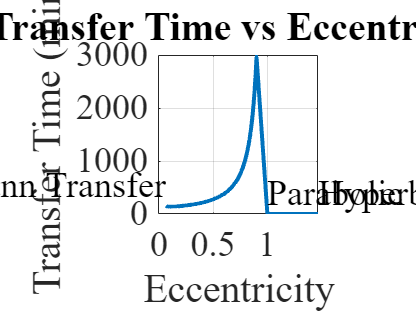

xlabel('Eccentricity', 'FontName', 'Times New Roman', 'FontSize', fs);
ylabel('Transfer Time (min)', 'FontName', 'Times New Roman', 'FontSize', fs);
title('Transfer Time vs Eccentricity', 'FontName', 'Times New Roman', 'FontSize', fs);
grid on;
axis square;
set(gca, 'FontName', 'Times New Roman', 'FontSize', fs);

% Annotate special points
hold on;
text(eccentricity(hohmannIndex), dt(hohmannIndex)/60, 'Hohmann Transfer', 'FontName', 'Times New Roman', 'FontSize', fs, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(eccentricity(parabolicIndex), dt(parabolicIndex)/60, 'Parabolic', 'FontName', 'Times New Roman', 'FontSize', fs, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
text(eccentricity(hyperbolicIndex), dt(hyperbolicIndex)/60, 'Hyperbolic', 'FontName', 'Times New Roman', 'FontSize', fs, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
hold off;

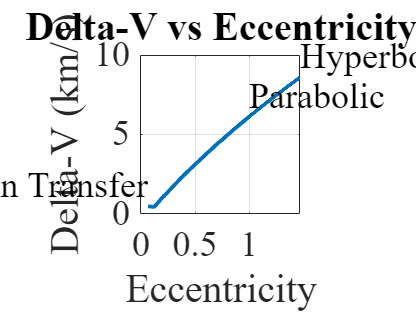


% Plot deltaV vs eccentricity
figure;
plot(eccentricity, deltaV, 'LineWidth', 2);
xlabel('Eccentricity', 'FontName', 'Times New Roman', 'FontSize', fs);
ylabel('Delta-V (km/s)', 'FontName', 'Times New Roman', 'FontSize', fs);
title('Delta-V vs Eccentricity', 'FontName', 'Times New Roman', 'FontSize', fs);
grid on;
axis square;
set(gca, 'FontName', 'Times New Roman', 'FontSize', fs);

% Annotate special points
hold on;
text(eccentricity(hohmannIndex), deltaV(hohmannIndex), 'Hohmann Transfer', 'FontName', 'Times New Roman', 'FontSize', fs, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(eccentricity(parabolicIndex), deltaV(parabolicIndex), 'Parabolic', 'FontName', 'Times New Roman', 'FontSize', fs, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
text(eccentricity(hyperbolicIndex), deltaV(hyperbolicIndex), 'Hyperbolic', 'FontName', 'Times New Roman', 'FontSize', fs, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
hold off;